# Deep Learning mit MATLAB

% Die MATLAB Deep LEarning Toolbox stellt einige Funktionen zum Arbeiten mit Tiefen NEuronalen Netzen zur Verfügung.
% Stellen Sie sicher, das der Arbeitspfad richtig eingestellt ist, da sonst
% die Bilder nicht gefunden werden kann. 

filename = "D:\Git\the-machine-learning-brick\Matlab";
cd(filename)


## Daten Laden und Data Store erstellen

filename = filename + "\Training\1_Runde_Schilder";
imdsSchilder = imageDatastore(filename, "IncludeSubfolders", true, "LabelSource", "foldernames");

## Explorative Datenanalyse

% numImgs = length(imdsZahlen.Files)
countEachLabel(imdsSchilder)

ans = 2×2 table
                Label                Count
    _____________________________    _____

    Geschwindigkeitsbegrenzung_30     136 
    Geschwindigkeitsbegrenzung_70     156 


%genau gleiche viele einträge von jedem Label
numPerLabel =min(countEachLabel(imdsSchilder).Count)

numPerLabel = 136

## Erzeuge Trainings- und Validierungsdatensatz

[imdsTrain, imdsValidation] = splitEachLabel(imdsSchilder, 0.8, "randomized");

## Defeniere Netzwerkschichten

% Einfaches CNN definieren

layers = [
    imageInputLayer([200, 200, 3])
    convolution2dLayer(3, 8, 'Padding', 'same', "Name", "conv_1")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name", "relu_1")
    maxPooling2dLayer(2, 'Stride', 2)
    convolution2dLayer(3, 16, 'Padding', 'same', "Name", "conv_2")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name", "relu_2")
    maxPooling2dLayer(2, 'Stride', 2)
    fullyConnectedLayer(2) 
    softmaxLayer
    classificationLayer
];


## Exploration des Netzwerkes

% layers(1).Name
% layers(1). InputSize
% layers(end-2).OutputSize

## Anpassen Hyperparameter

%sicherstellen das alle Bilder die gleiche größe haebn
augTrain  = augmentedImageDatastore([200, 200, 3], imdsTrain);
augVal = augmentedImageDatastore([200, 200, 3], imdsValidation);
% Trainingsparameter Schlake
% opts = trainingOptions("adam", "ValidationData", augVal, "Shuffle", "every-epoch", "Plots", "training-progress","InitialLearnRate",0.01);
% Trainingsparameter 
options = trainingOptions('adam', ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 300, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false, ...
    'Plots', 'training-progress');

## Training

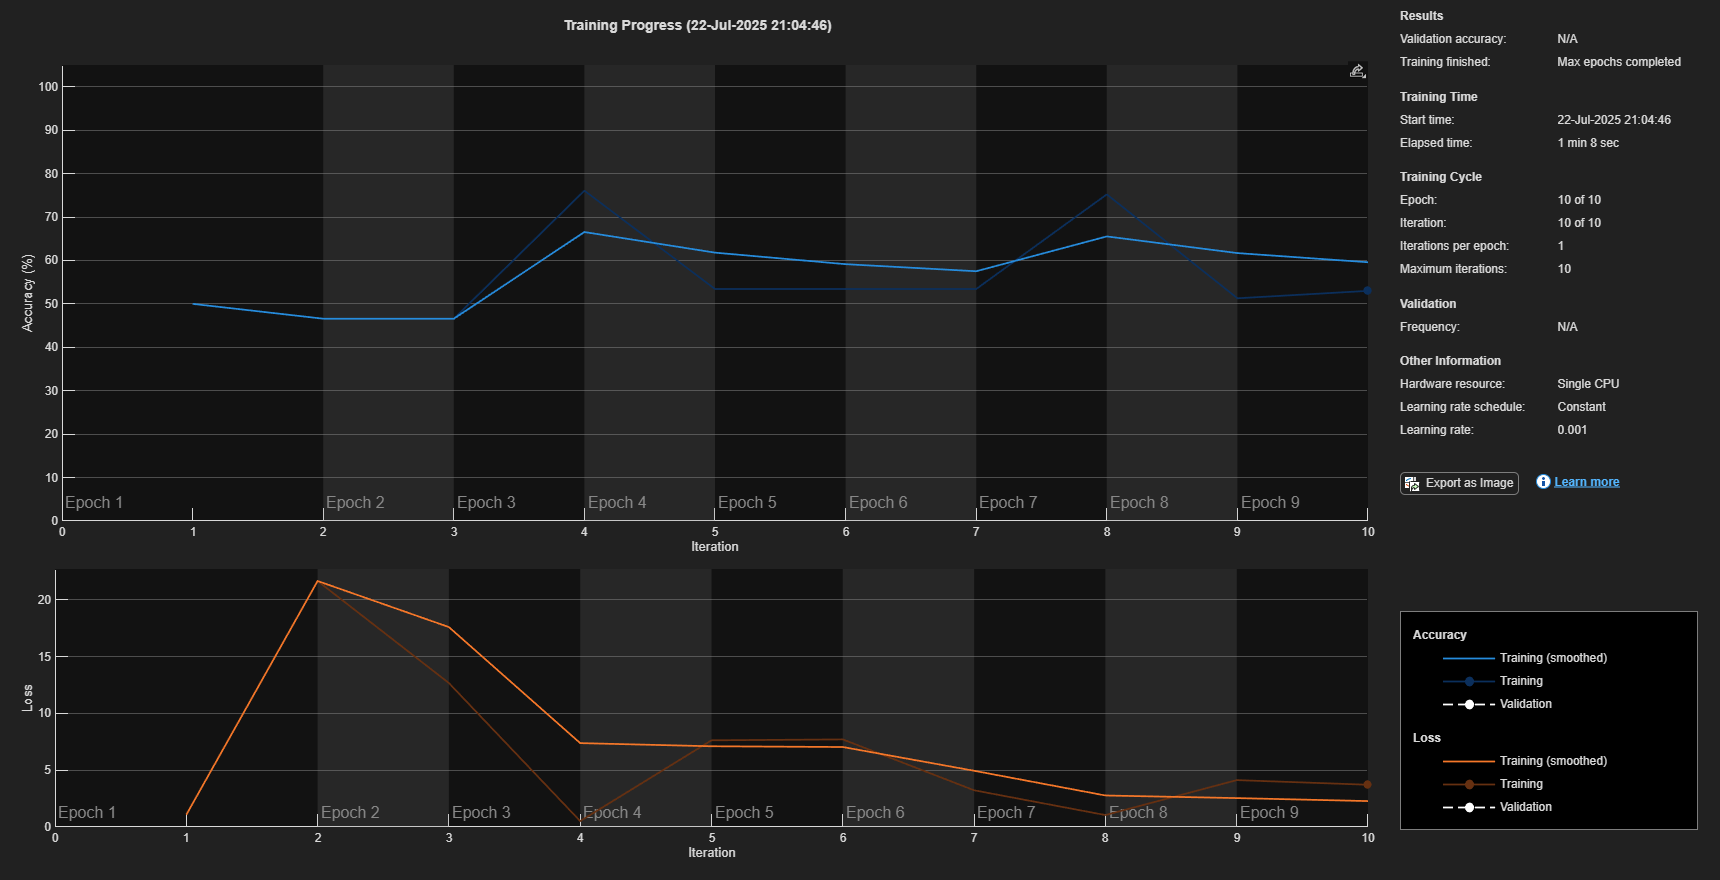

net = trainNetwork(augTrain, layers, options);

## Schätzung

% Testen des Neuronalen Netzes
trainPreds = classify(net,augTrain);
testPreds = classify(net,augVal);

## Evaluierung

% Evaluierung des Modelles
confMat = confusionmat(imdsTrain.Labels, trainPreds);
accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 74.79%


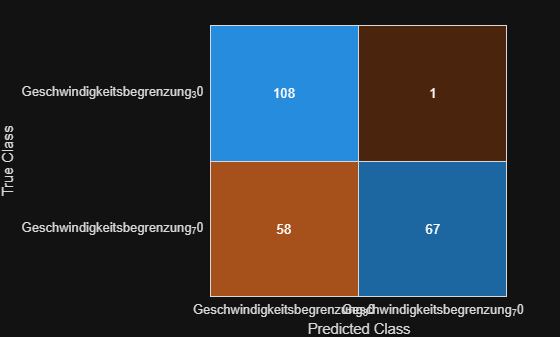

confusionchart(imdsTrain.Labels, trainPreds);

confMat = confusionmat(imdsValidation.Labels, testPreds);
accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 77.59%


confusionchart(imdsValidation.Labels, testPreds);

% Export 
lgraph = layerGraph(net.Layers);
lgraph.Layers

ans =   12×1 Layer array with layers:

     1   'imageinput'    Image Input             200×200×3 images with 'zerocenter' normalization
     2   'conv_1'        2-D Convolution         8 3×3×3 convolutions with stride [1  1] and padding 'same'
     3   'batchnorm_1'   Batch Normalization     Batch normalization with 8 channels
     4   'relu_1'        ReLU                    ReLU
     5   'maxpool_1'     2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv_2'        2-D Convolution         16 3×3×8 convolutions with stride [1  1] and padding 'same'
     7   'batchnorm_2'   Batch Normalization     Batch normalization with 16 channels
     8   'relu_2'        ReLU                    ReLU
     9   'maxpool_2'     2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    10   'fc'            Fully Connected         2 fully connected la

lgraph = removeLayers(lgraph, 'batchnorm_1');
lgraph = removeLayers(lgraph, 'batchnorm_2');
lgraph = connectLayers(lgraph, 'conv_1', 'relu_1');
lgraph = connectLayers(lgraph, 'conv_2', 'relu_2');
net_no_bn = assembleNetwork(lgraph);
classify(net_no_bn, augVal);
exportNetworkToTensorFlow(net_no_bn,"ML-Model/tf_model")